prob1

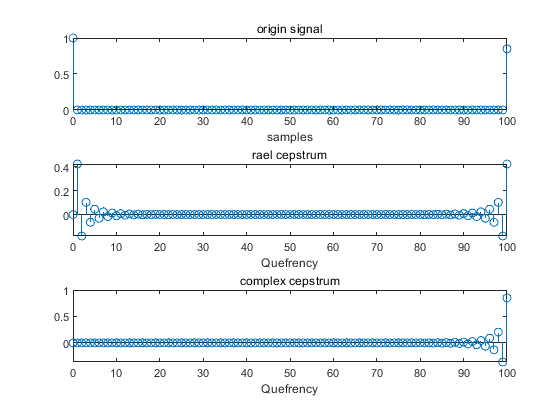

[y, fs] = audioread('test_16k.wav');
n = 0:100;
y = (n==0) + 0.85*(n-100==0);
N = length(y);
t = (0:N-1)/fs;


nfft = N;
[cY, rY] = Cepstrum(y, nfft);
quefrency_c = (0:length(cY)-1)/fs;
quefrency_r = (0:length(rY)-1)/fs;

figure
subplot(311)
stem(0:length(y)-1, y)
title('origin signal'), xlabel('samples')

subplot(312)
stem(0:length(rY)-1, rY), xlabel('Quefrency'), title('rael cepstrum')


subplot(313)
stem(0:length(cY)-1, cY), xlabel('Quefrency'), title('complex cepstrum')
saveas(gcf, 'D:/作业提交/大三 下/语音信号处理/lab6/P1.png', 'png')

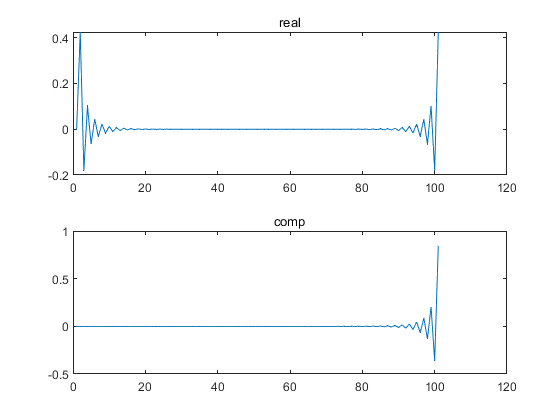


% test
yhat_c = cceps(y);
yhat_r = rceps(y);

figure
subplot(211), plot(yhat_r), title('real')
subplot(212), plot(yhat_c), title('comp')

Prob2

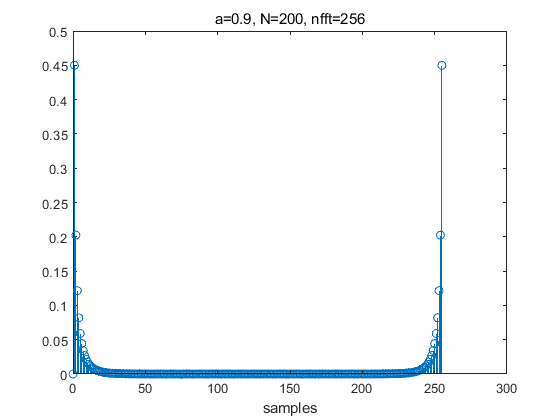

clc, clear
% parameters, change for different cases
a = 0.9;   % 0.5, 0.9
N = 200;   % 10, 200
nfft = 256;   % 10, 16, 200, 256
n = 0:N-1;
y = a.^n .* (n>=0);
% real cepstrum
Y = fft(y, nfft);
Y_log = log(abs(Y));
Y_cep = ifft(Y_log);

figure;
stem(0:length(Y_cep)-1, Y_cep), title('a=0.9, N=200, nfft=256'), xlabel('samples')
saveas(gcf, "D:/作业提交/大三 下/语音信号处理/lab6/P2_16_r.png", 'png')

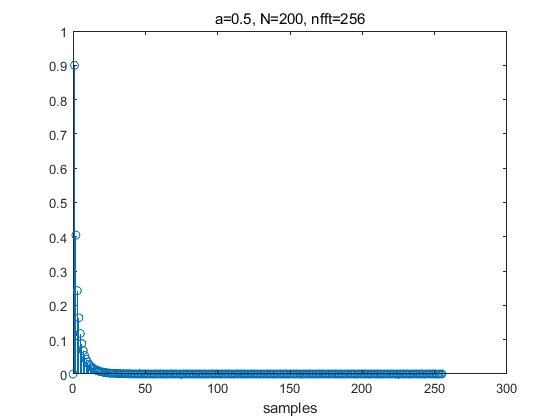


% complex cepstrum
phase = unwrap(angle(Y));
Y_ccep = Y_log + 1i*phase;
Y_ccep = ifft(Y_ccep);
figure
stem(0:length(Y_ccep)-1, Y_ccep), title('a=0.5, N=200, nfft=256'), xlabel('samples')
saveas(gcf, "D:/作业提交/大三 下/语音信号处理/lab6/P2_16_c.png", 'png')

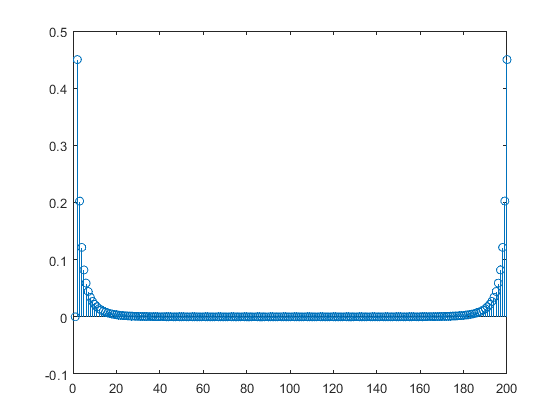


% test
hat = rceps(y);
figure
stem(hat)

当nfft数等于或大于原信号长度时效果最好

function [ccepstrum, rcepstrum] = Cepstrum(y, nfft)
    % real cepstrum
    Y = fft(y, nfft);
    Y_log = log(abs(Y));
    rcepstrum  =ifft(Y_log, 'symmetric');
        
    %complex cepstrum
    phase = unwrap(angle(Y));
    ccepstrum = log(abs(Y)) + 1j * unwrap(angle(Y));   % 相位展开
    ccepstrum = real(ifft(ccepstrum));
end